# Create Grid World Environment

For this example, consider a 5-by-5 grid world with the following rules:

- A 5-by-5 grid world bounded by borders, with 4 possible actions (North = 1, South = 2, East = 3, West = 4).

- The agent begins from cell [2,1] (second row, first column).

- The agent receives reward +10 if it reaches the terminal state at cell [5,5] (blue).

- The environment contains a special jump from cell [2,4] to cell [4,4] with +5 reward.

- The agent is blocked by obstacles in cells [3,3], [3,4], [3,5] and [4,3] (black cells).

- All other actions result in -1 reward.

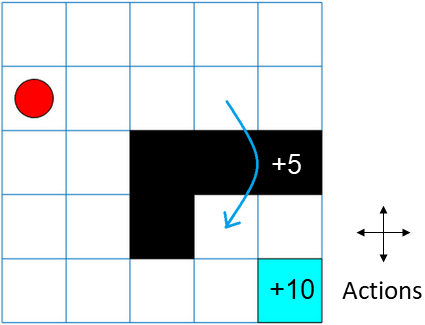

First, create a `GridWorld` object using the `createGridWorld` function.

%help createGridWorls


GW = createGridWorld(5,5)

Now, set the initial, terminal and obstacle states.

GW.CurrentState = '[1,1]';

GW =   GridWorld with properties:

          GridSize: [5 5]
      CurrentState: "[1,1]"
            States: [25×1 string]
           Actions: [4×1 string]
                 T: [25×25×4 double]
                 R: [25×25×4 double]
    ObstacleStates: [0×1 string]
    TerminalStates: [0×1 string]


GW.TerminalStates = '[5,5]';
GW.ObstacleStates = ["[3,3]";"[3,4]";"[3,5]";"[4,3]"];

Update the state transition matrix for the obstacle states and set the jump rule over the obstacle states.

updateStateTranstionForObstacles(GW)
GW.T(state2idx(GW,"[2,4]"),:,:) = 0;
GW.T(state2idx(GW,"[2,4]"),state2idx(GW,"[4,4]"),:) = 1;
%GW.T(state2idx(GW,"[5,2]"),:,:) = 0;
%GW.T(state2idx(GW,"[5,2]"),state2idx(GW,"[5,4]"),:) = 5;

Next, define the rewards in the reward transition matrix.

nS = numel(GW.States);
nA = numel(GW.Actions);
GW.R = -1*ones(nS,nS,nA);
GW.R(state2idx(GW,"[2,4]"),state2idx(GW,"[4,4]"),:) = 1;
GW.R(:,state2idx(GW,GW.TerminalStates),:) = 10;

Now, use `rlMDPEnv` to create a grid world environment using the `GridWorld` object `GW`.

env = rlMDPEnv(GW)

You can visualize the grid world environment using the `plot` function.

env =   rlMDPEnv with properties:

       Model: [1×1 rl.env.GridWorld]
    ResetFcn: []


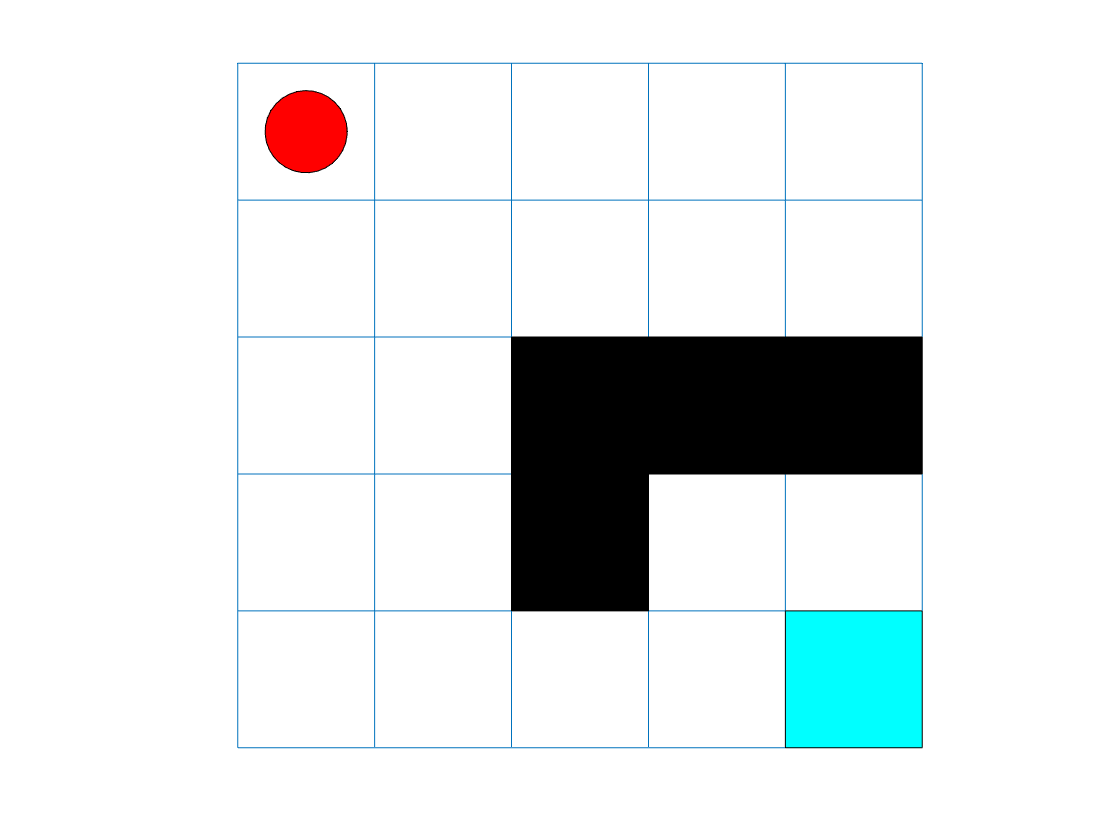

plot(env)

*Copyright 2018 The MathWorks, Inc.*